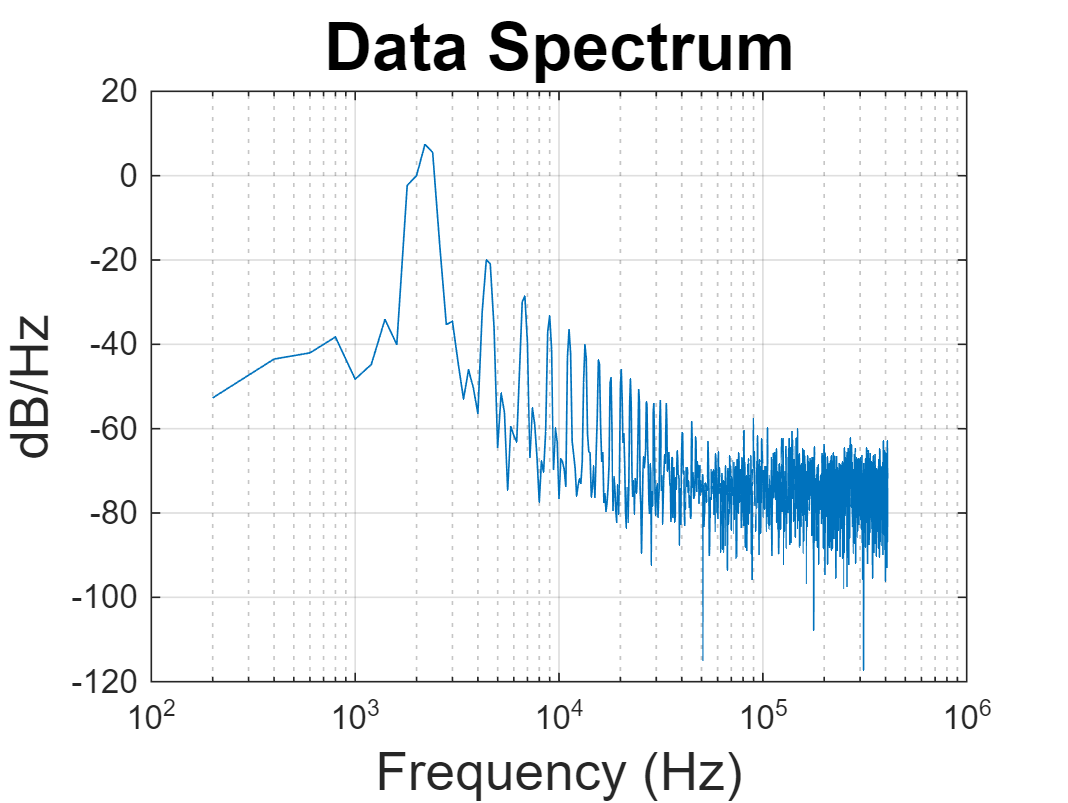

@Freq = 2000.000, SNR = 38.521 dB, SNDR = -7.888 dB, SFDR = 56.397 dB, HD2 = 56.397 and HD3 = 61.582


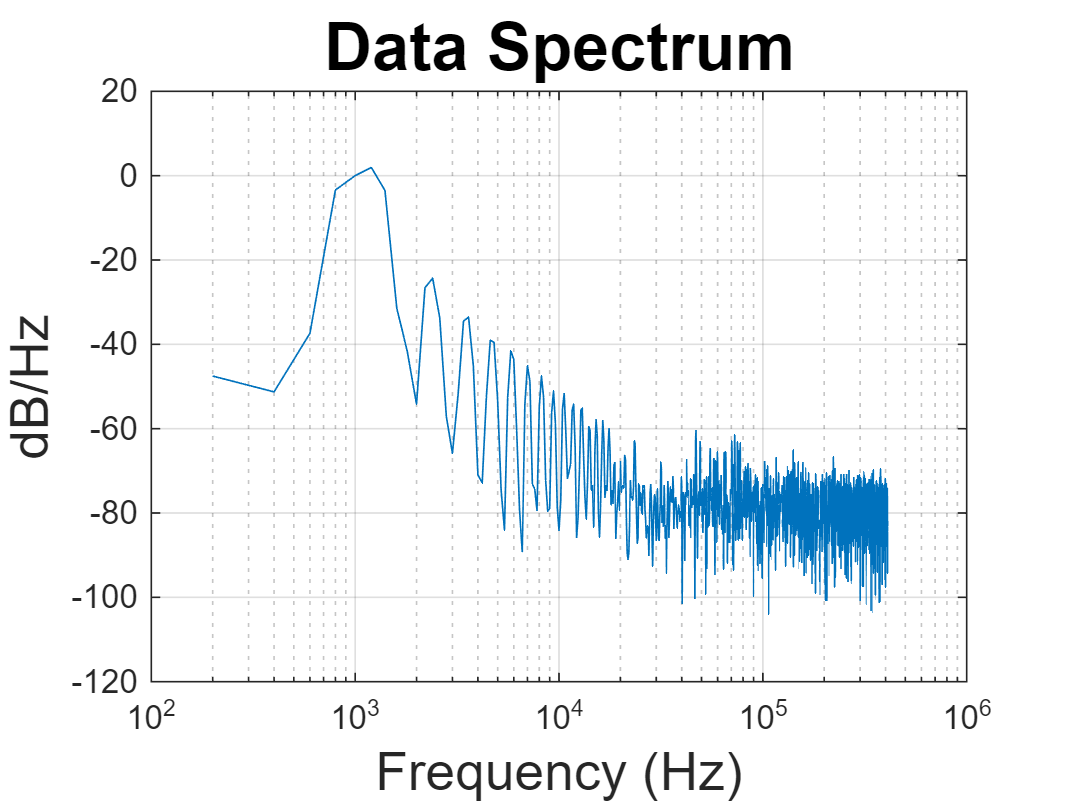

@Freq = 1000.000, SNR = 43.162 dB, SNDR = -1.199 dB, SFDR = 54.104 dB, HD2 = 54.104 and HD3 = 65.974


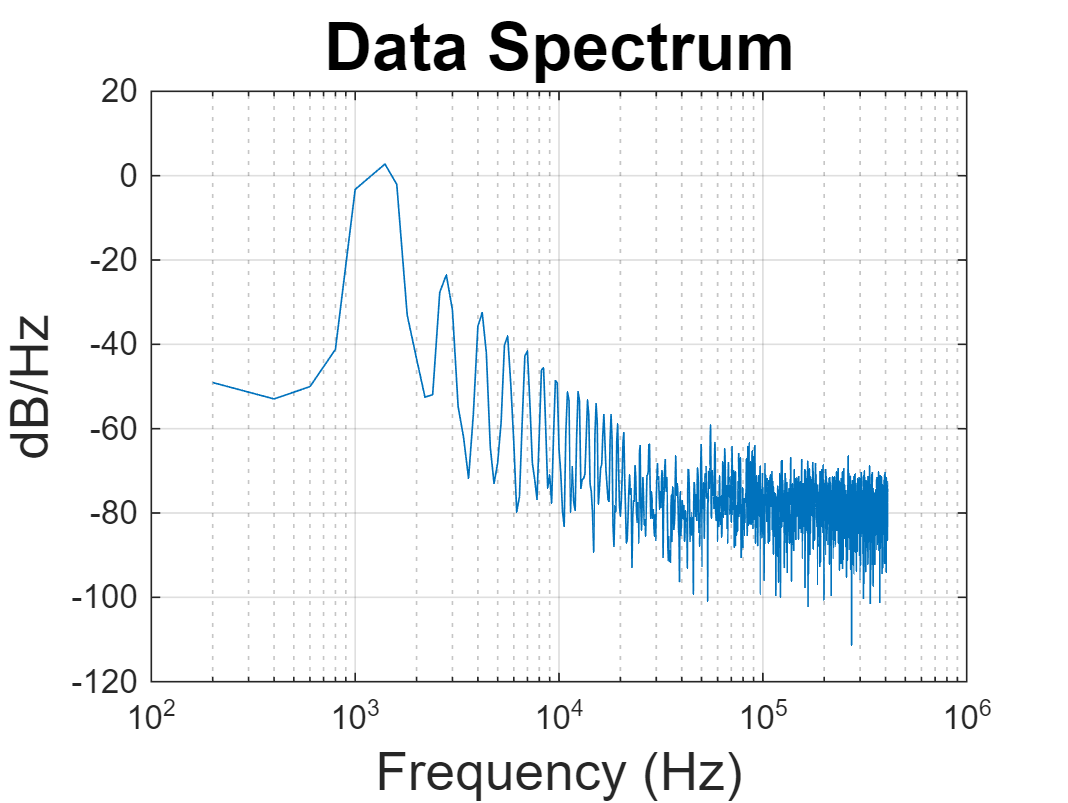

@Freq = 1200.000, SNR = 42.223 dB, SNDR = -2.191 dB, SFDR = 51.967 dB, HD2 = 51.967 and HD3 = 71.744


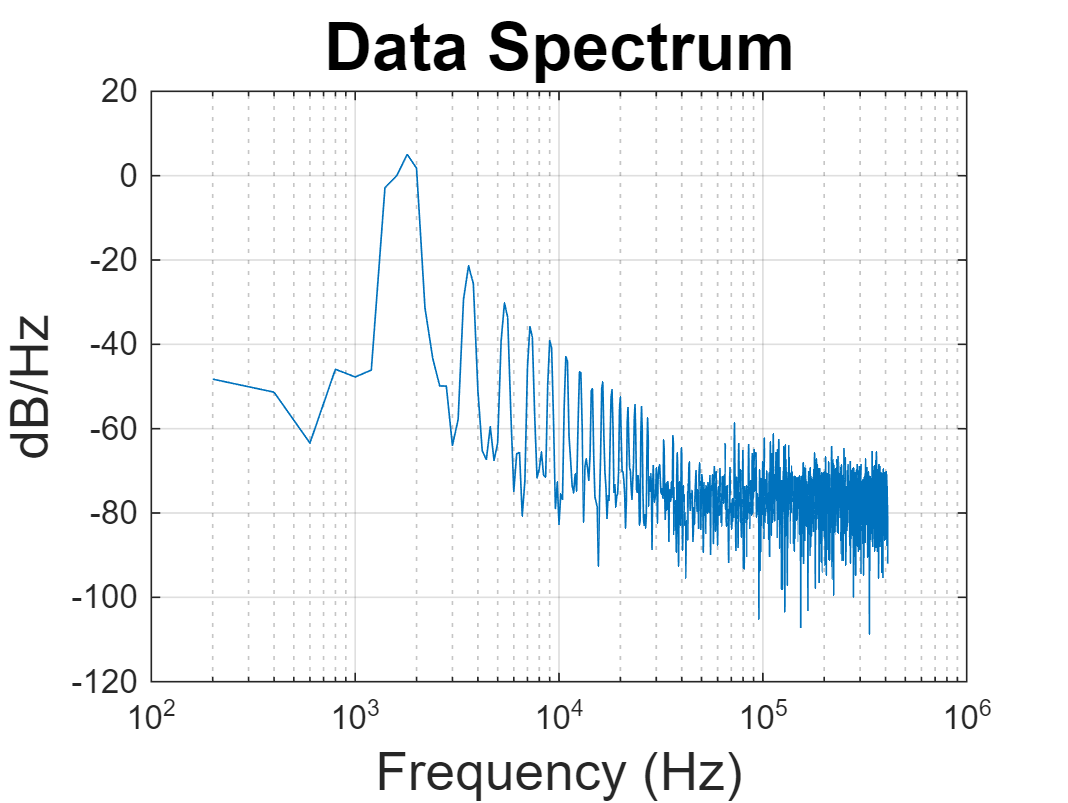

@Freq = 1600.000, SNR = 44.029 dB, SNDR = -4.998 dB, SFDR = 57.769 dB, HD2 = 57.769 and HD3 = 67.465


@Freq = 2000.000, SNR = 38.521 dB, SNDR = -7.888 dB, SFDR = 56.397 dB, HD2 = 56.397 and HD3 = 61.582


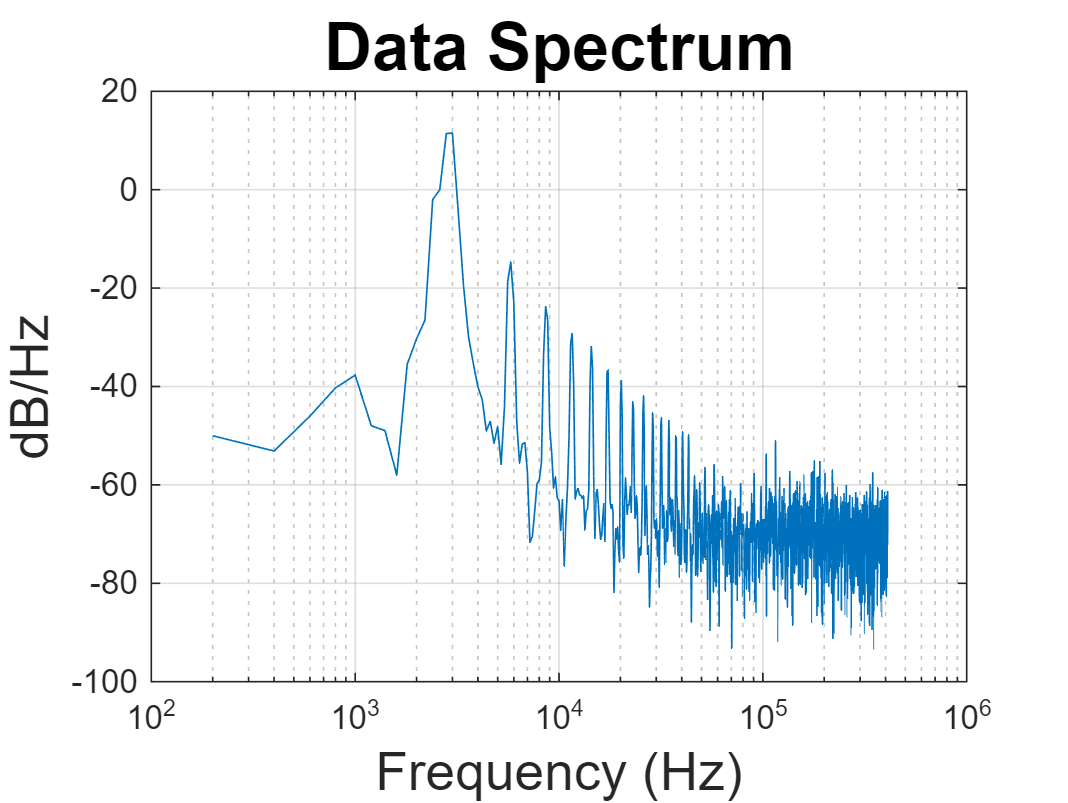

@Freq = 2600.000, SNR = 43.467 dB, SNDR = -12.810 dB, SFDR = 55.865 dB, HD2 = 55.865 and HD3 = 59.754


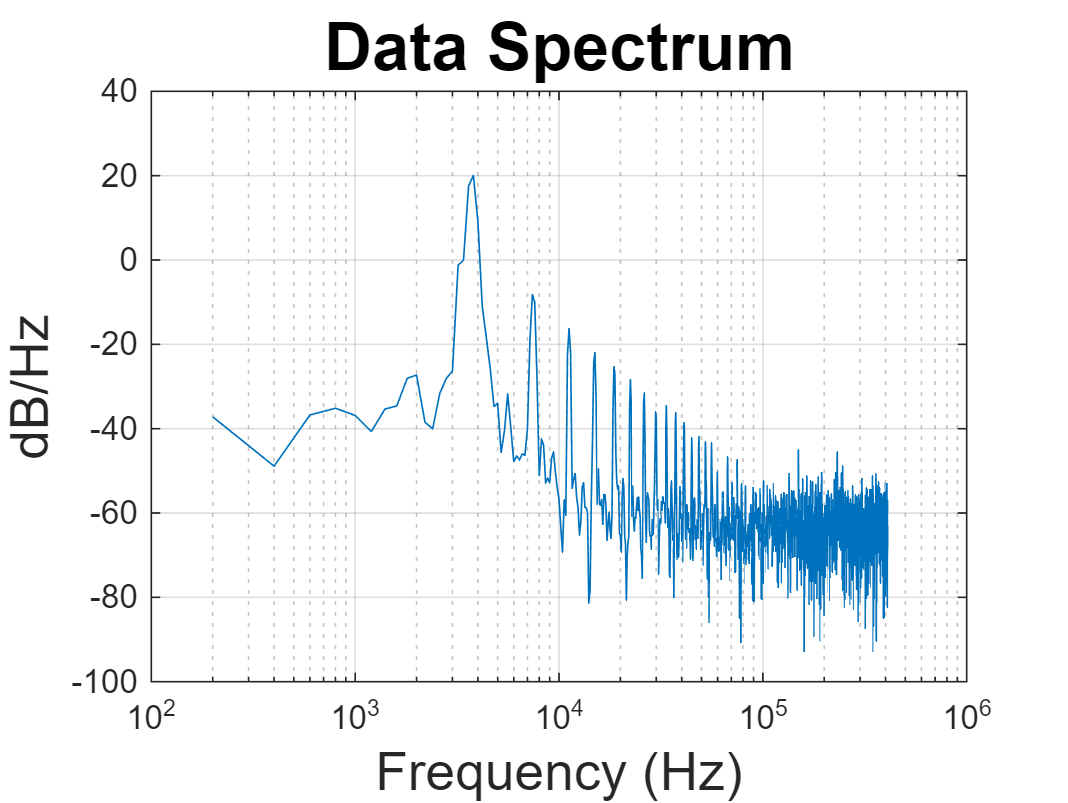

@Freq = 3400.000, SNR = 41.537 dB, SNDR = -20.467 dB, SFDR = 46.301 dB, HD2 = 46.301 and HD3 = 63.292


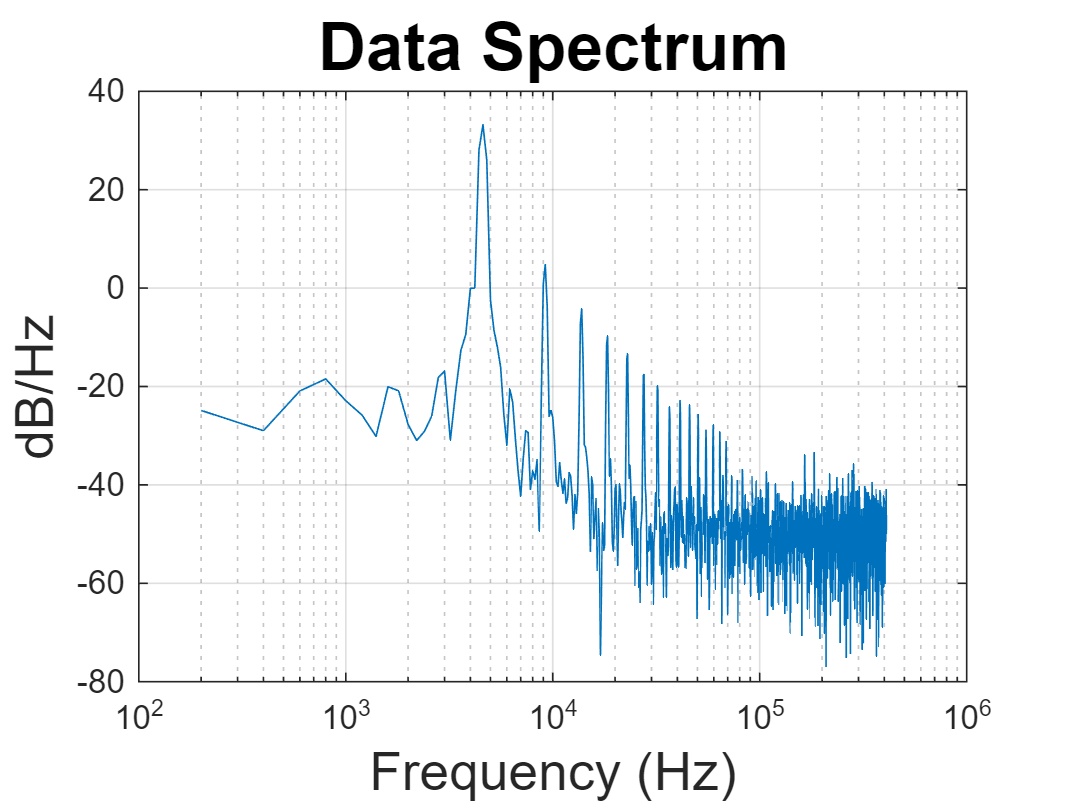

@Freq = 4200.000, SNR = 41.726 dB, SNDR = -33.196 dB, SFDR = 34.908 dB, HD2 = 34.908 and HD3 = 49.015


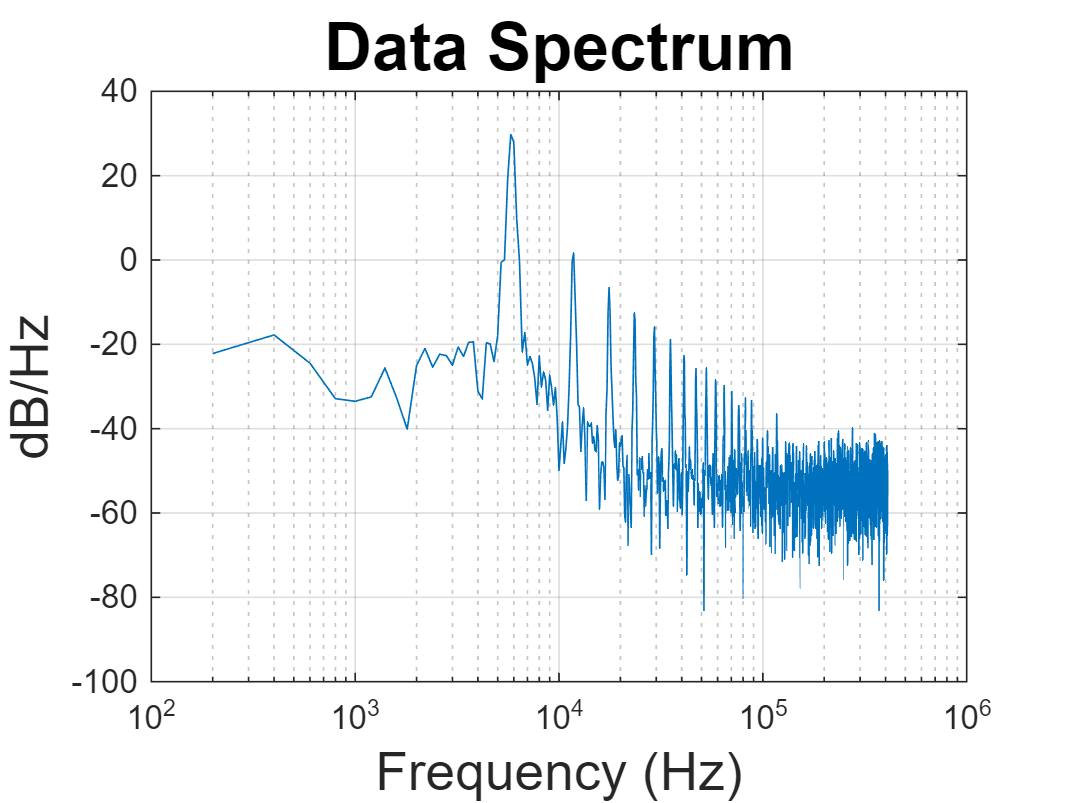

@Freq = 5400.000, SNR = 38.991 dB, SNDR = -30.465 dB, SFDR = 44.852 dB, HD2 = 44.852 and HD3 = 47.978


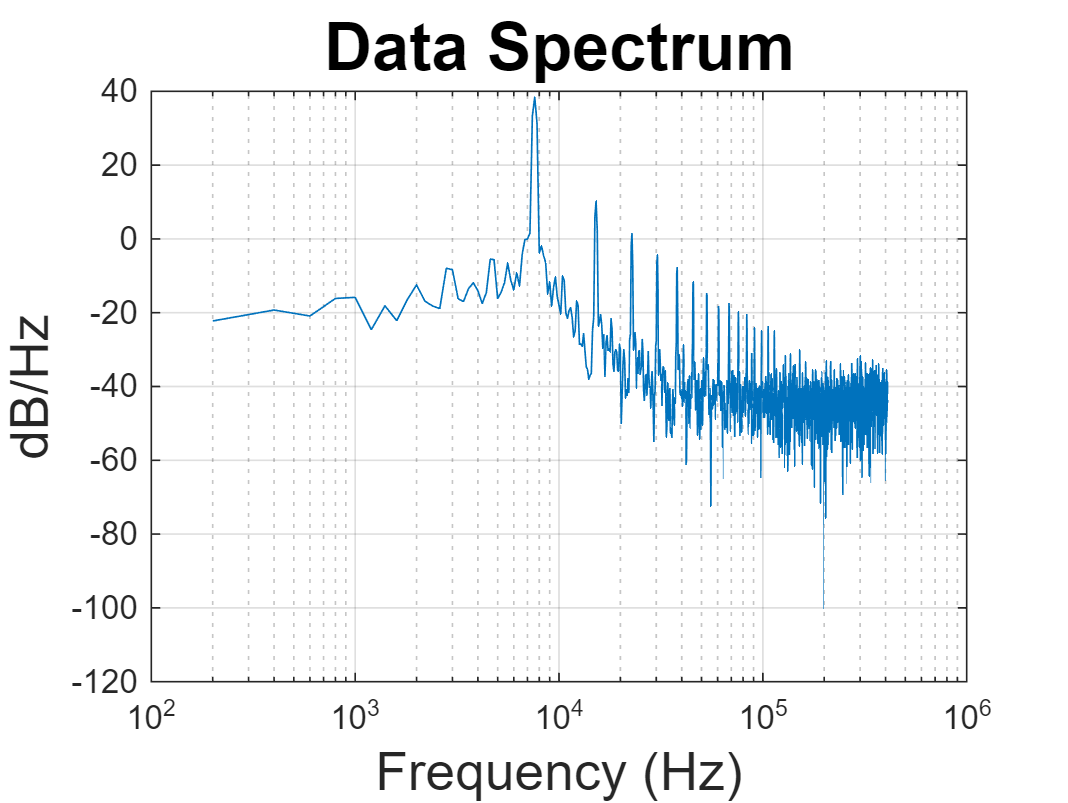

@Freq = 7000.000, SNR = 34.030 dB, SNDR = -38.430 dB, SFDR = 33.065 dB, HD2 = 38.025 and HD3 = 33.065


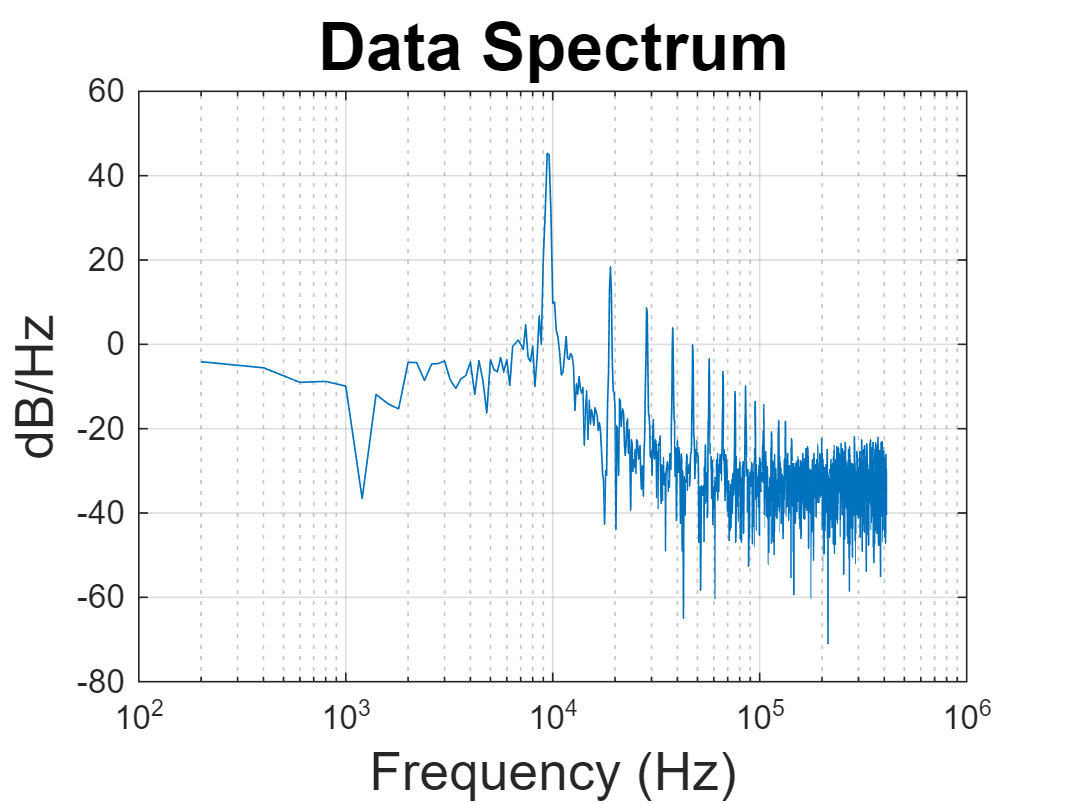

@Freq = 8800.000, SNR = 31.892 dB, SNDR = -46.585 dB, SFDR = 23.962 dB, HD2 = 32.383 and HD3 = 23.962


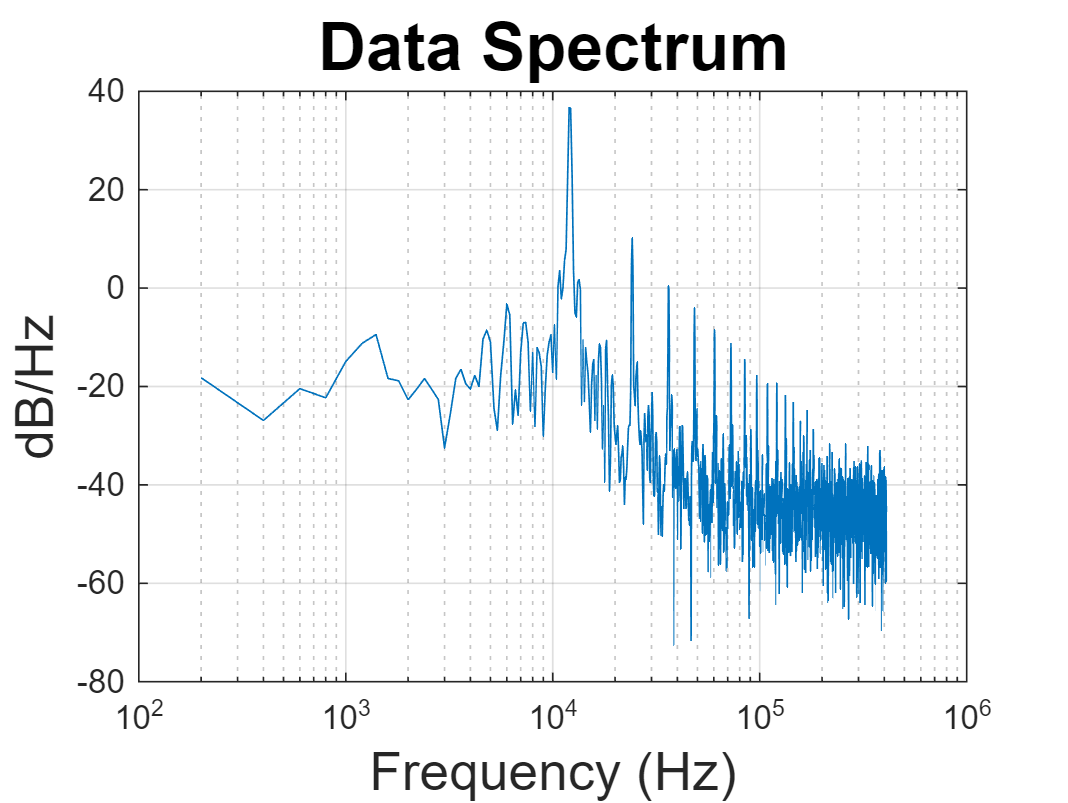

@Freq = 11200.000, SNR = 29.382 dB, SNDR = -38.068 dB, SFDR = 38.437 dB, HD2 = 38.437 and HD3 = 44.525


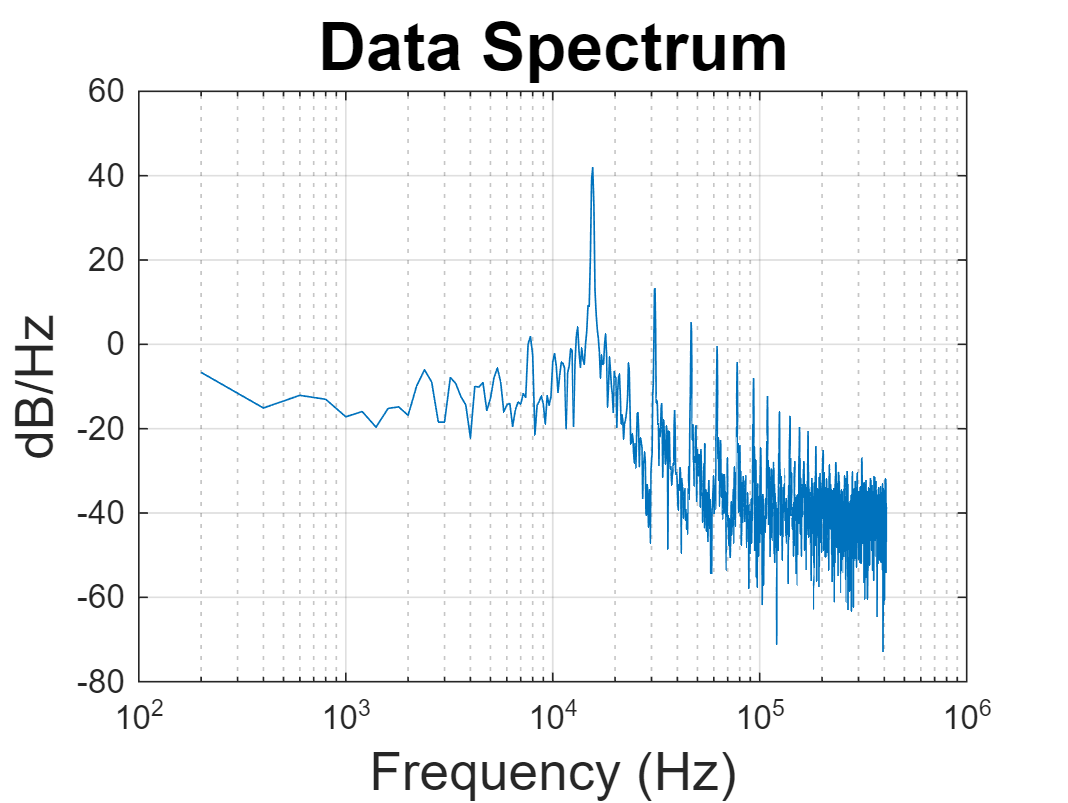

@Freq = 14400.000, SNR = 28.320 dB, SNDR = -42.357 dB, SFDR = 35.050 dB, HD2 = 35.050 and HD3 = 36.193


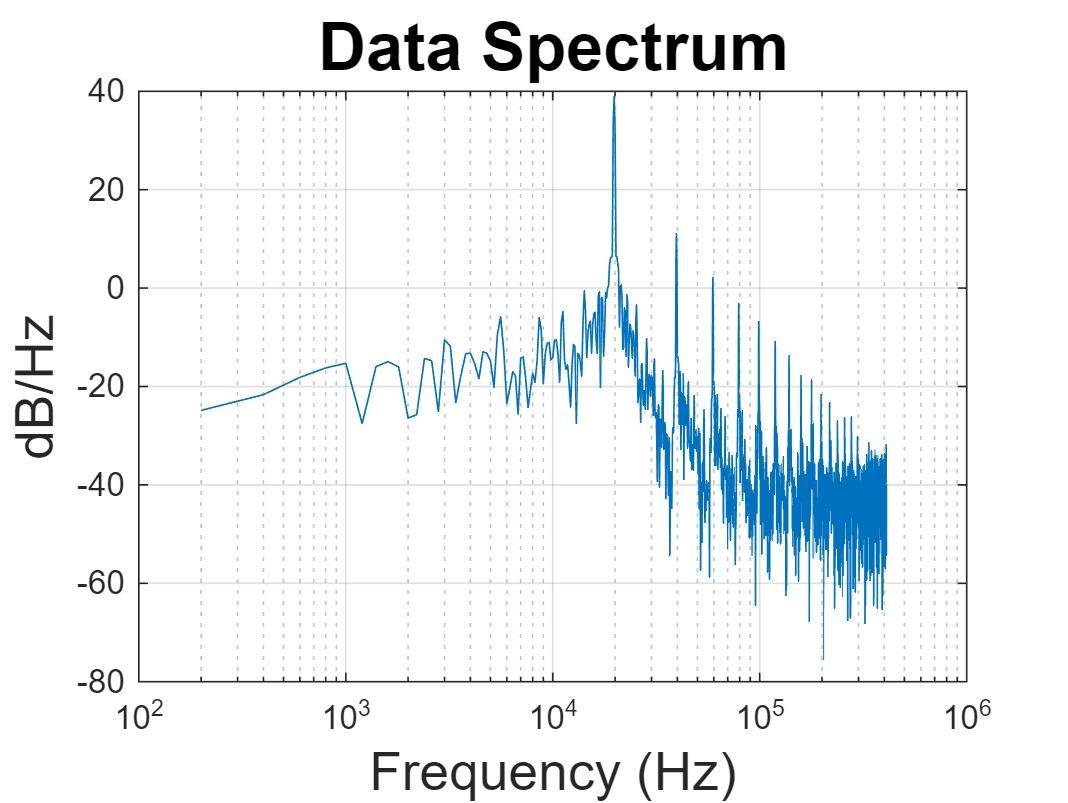

@Freq = 18400.000, SNR = 28.238 dB, SNDR = -39.055 dB, SFDR = 40.626 dB, HD2 = 54.236 and HD3 = 40.626


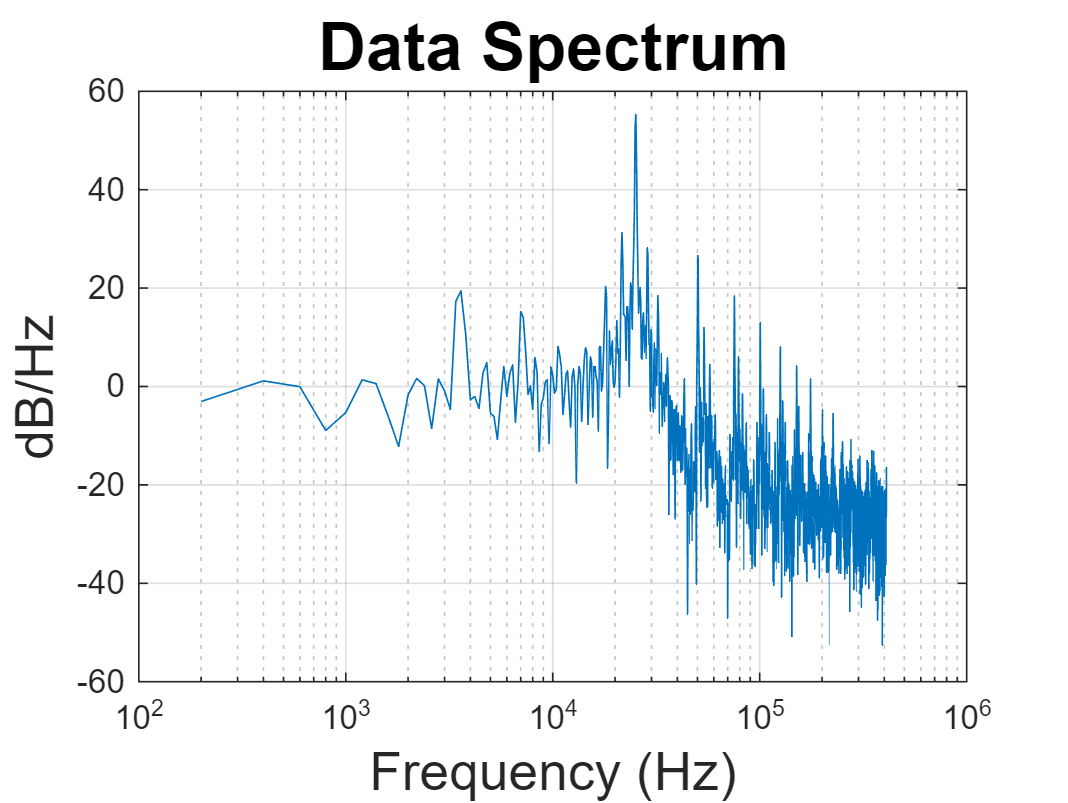

@Freq = 23400.000, SNR = 20.660 dB, SNDR = -55.829 dB, SFDR = 7.532 dB, HD2 = 7.532 and HD3 = 30.073


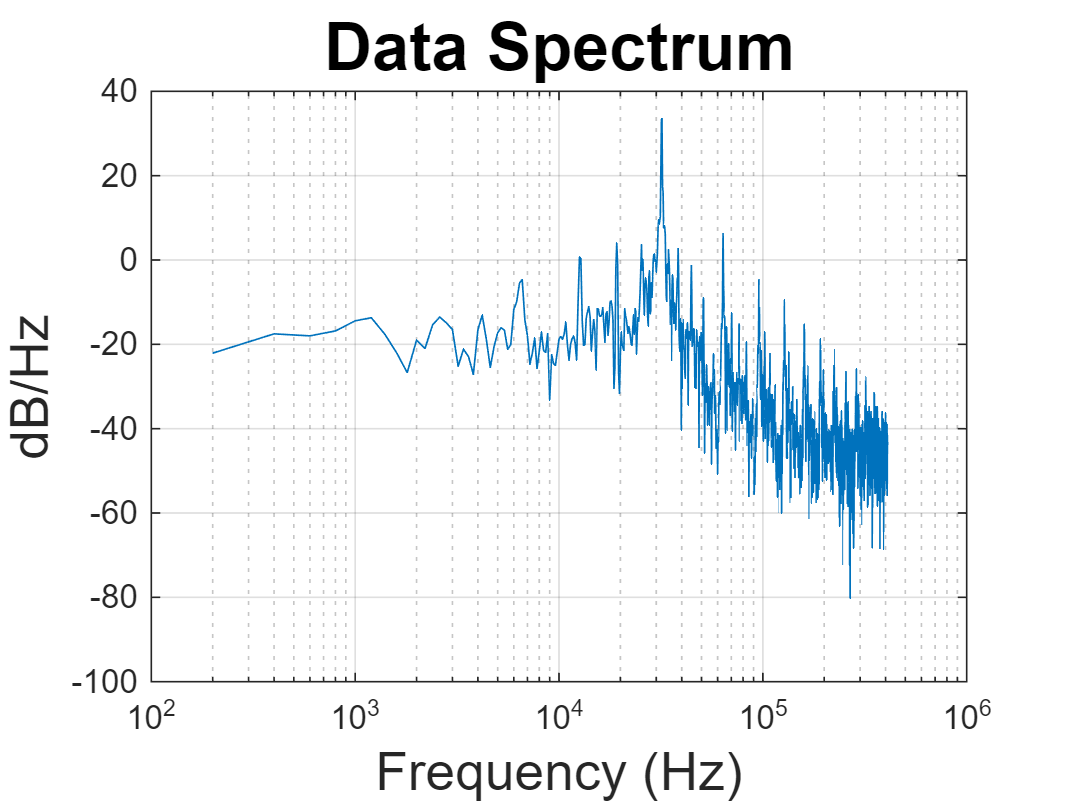

@Freq = 29800.000, SNR = 18.277 dB, SNDR = -35.137 dB, SFDR = 37.488 dB, HD2 = 40.246 and HD3 = 37.488


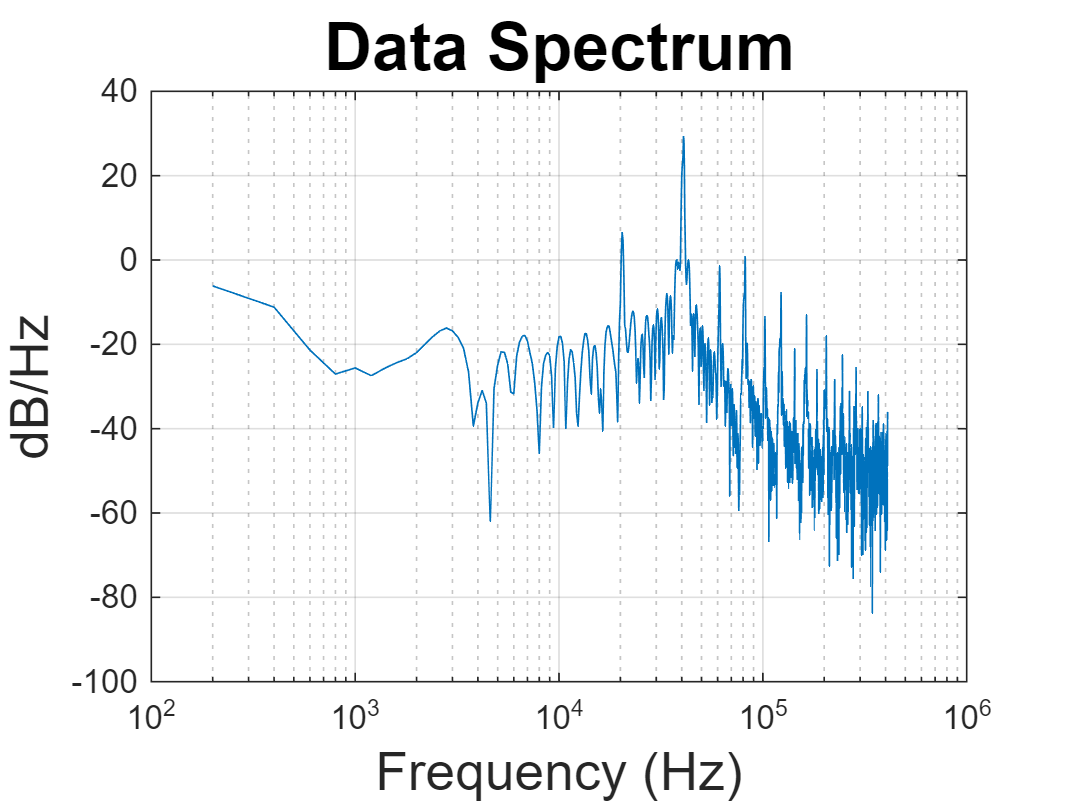

@Freq = 38000.000, SNR = 18.926 dB, SNDR = -32.350 dB, SFDR = 47.904 dB, HD2 = 54.464 and HD3 = 47.904


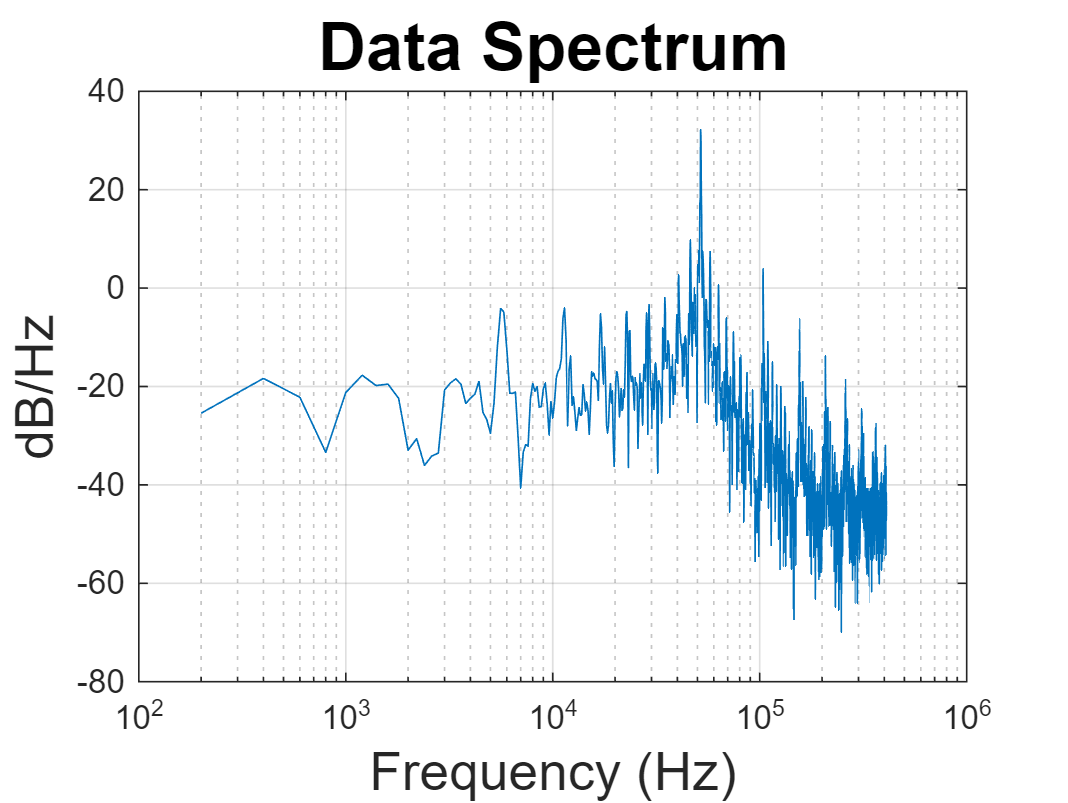

@Freq = 48400.000, SNR = 15.560 dB, SNDR = -33.348 dB, SFDR = 42.548 dB, HD2 = 47.619 and HD3 = 42.548


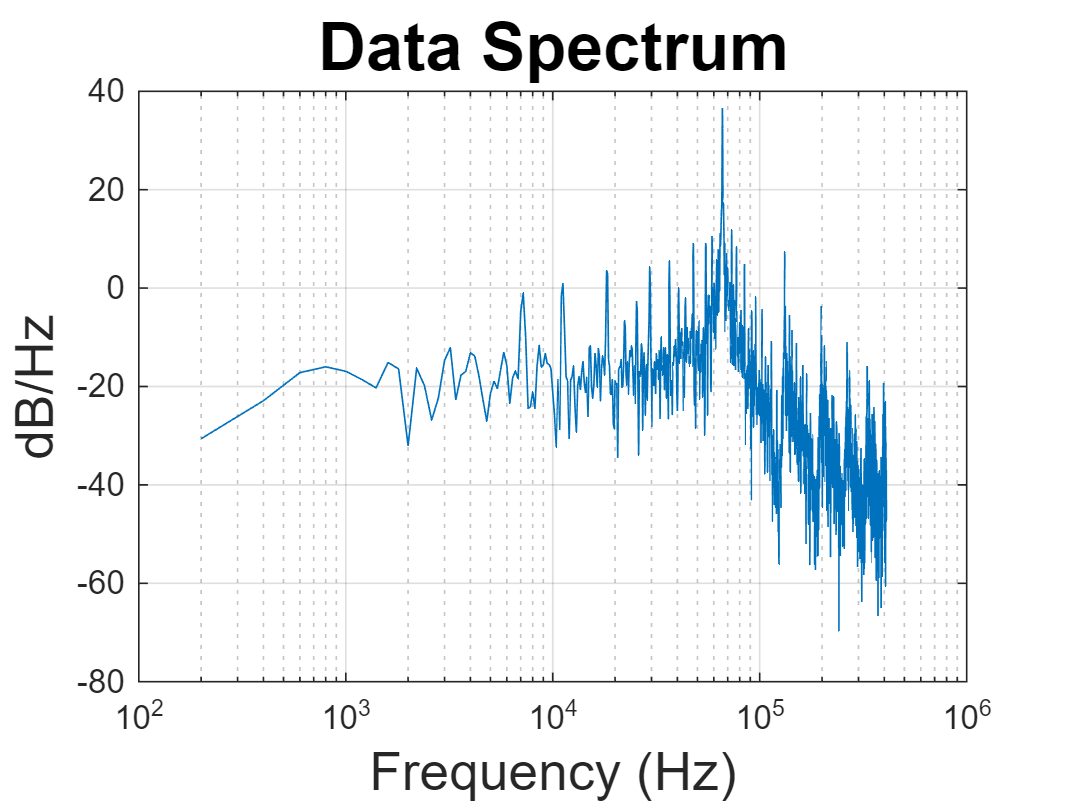

@Freq = 61600.000, SNR = 12.729 dB, SNDR = -36.959 dB, SFDR = 40.425 dB, HD2 = 40.425 and HD3 = 42.413


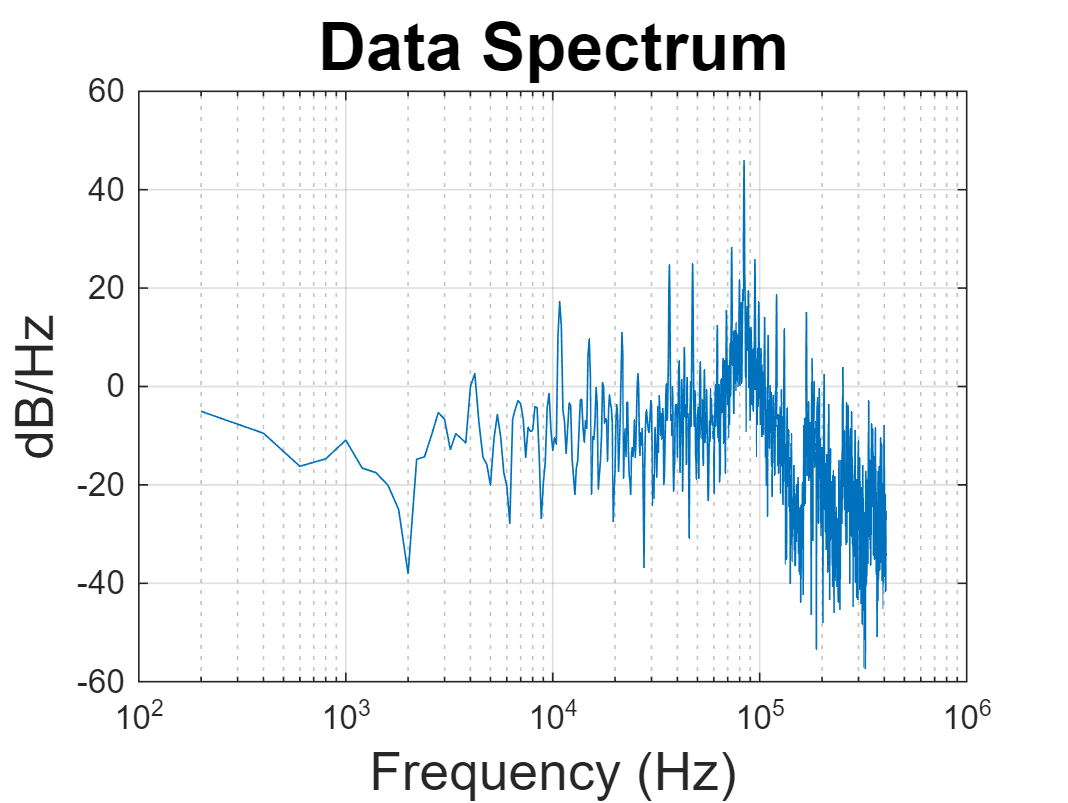

@Freq = 78400.000, SNR = 11.494 dB, SNDR = -47.140 dB, SFDR = 24.602 dB, HD2 = 24.602 and HD3 = 31.994


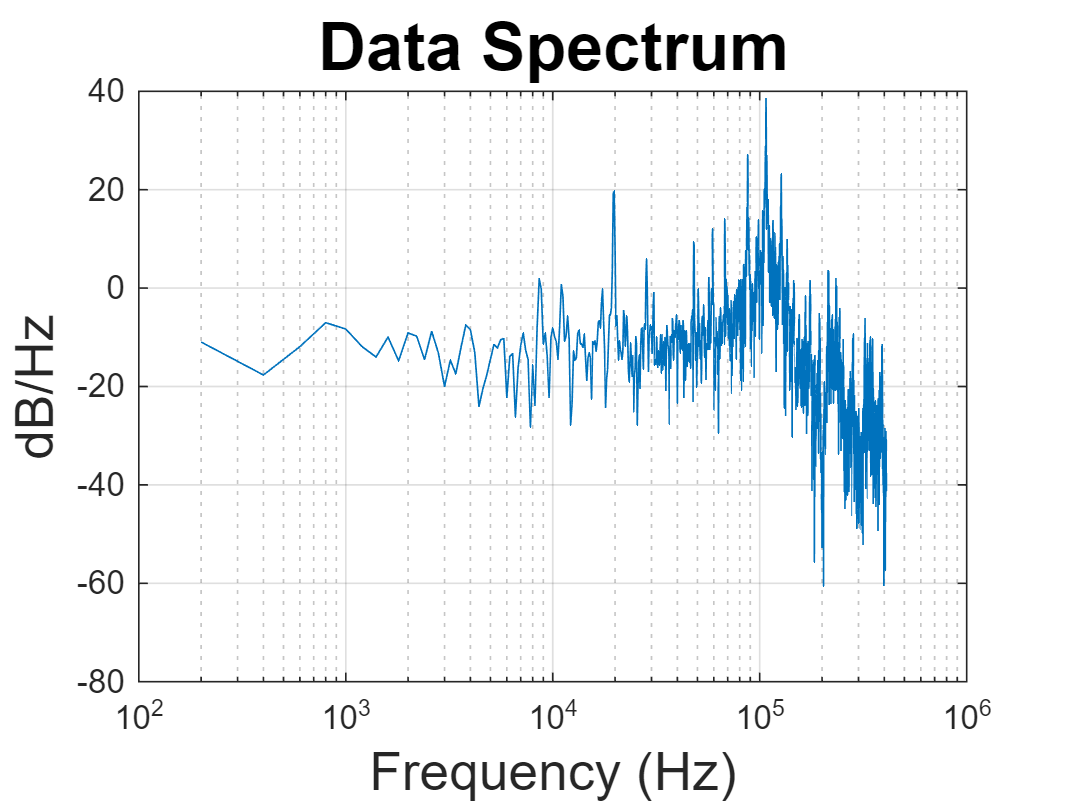

@Freq = 100000.000, SNR = 3.616 dB, SNDR = -41.403 dB, SFDR = 25.741 dB, HD2 = 48.724 and HD3 = 25.741


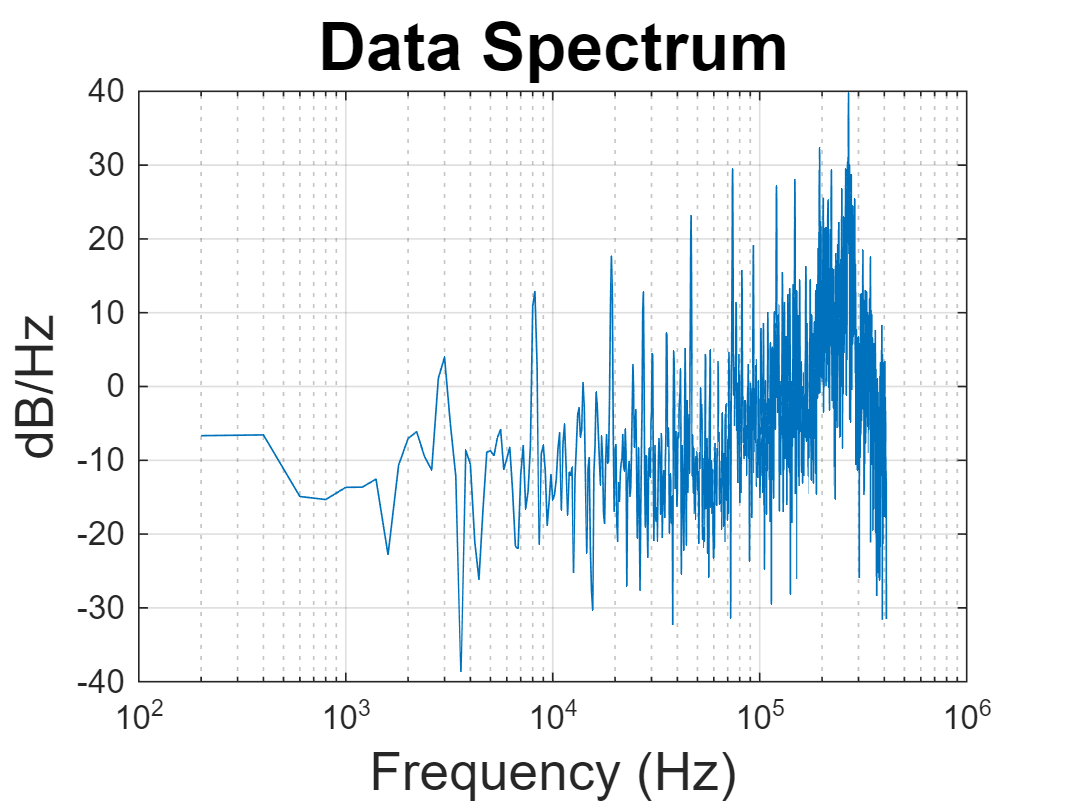

@Freq = 250000.000, SNR = -4.865 dB, SNDR = -47.438 dB, SFDR = 2.613 dB, HD2 = 2.613 and HD3 = 13.143


clearvars
freq_array = readtable('./ADC_Data/CML-Data/EthanTBBoard3_12-1-BYPASS-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
% freq_array = freq_array*1e6;
% freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/CML-Data/EthanTBBoard3_12-1-BYPASS-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'.0Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));
    rising_edge_indices = find(diff(data_EOC) == 1)+3;
    
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index); 
    end

    data_NewDec = data_NewCode;

    Fs=819.2e3;
    num_segments=1;
    f_signal = freq_array(i)-100;
    f_s = Fs;
    BW =Fs/2;
    sample_size=2^floor(log2(length(data_NewDec)));
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    % fs = 1e6;                 % Sampling rate in Hz
    % N = length(data_NewDec);                  % Number of samples
    % bit_depth = 9;            % ADC bit resolution
    % V_min = 0;              % Minimum input voltage
    % V_max = 1;               % Maximum input voltage
    % 
    % % Map codes to voltage
    % voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    % 
    % % Create time axis
    % t = (0:N-1) / fs;
    % 
    % % Plot the reconstructed waveform
    % figure;
    % plot(t, voltages, 'b');
    % title('Reconstructed Time-Domain Waveform');
    % xlabel('Time (s)');
    % ylabel('Amplitude (V)');
    % grid on;
end

save('BigSet.mat', 'BigSet');

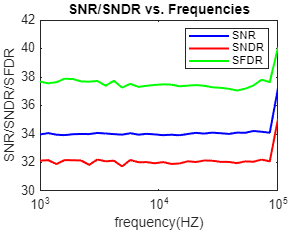

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;